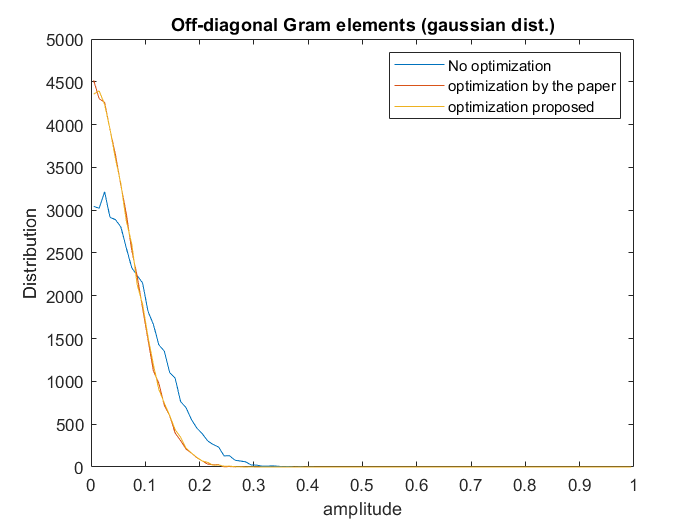

rng(100)
%D = rand(100,200);
D = normrnd(0,1,100,200);
D_0 = optimise(D,60,0.02);
D_1 = optimise_new(D,60,1);

figure;
my_hist(off_diag_gram(D));
hold on;
my_hist(off_diag_gram(D_0));
hold on;
my_hist(off_diag_gram(D_1));
xlabel("amplitude")
ylabel("Distribution")
title("Off-diagonal Gram elements (gaussian dist.)")
legend('No optimization','optimization by the paper','optimization proposed');

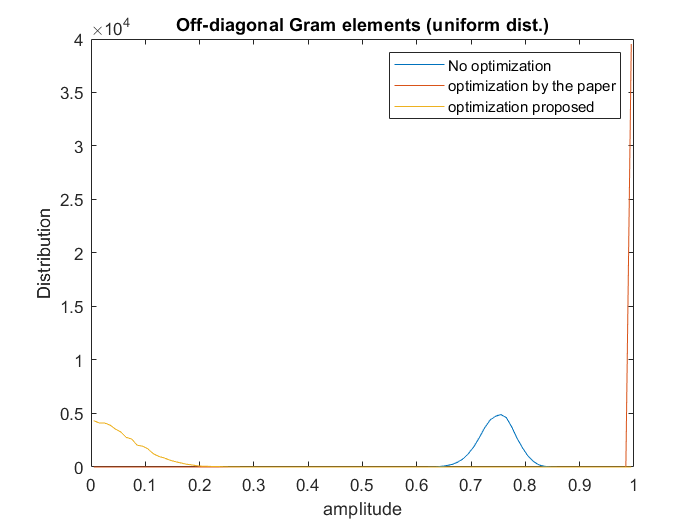


D = rand(100,200);
%D = normrnd(0,1,100,200);
D_0 = optimise(D,60,0.02);
D_1 = optimise_new(D,60,1);

figure;
my_hist(off_diag_gram(D));
hold on;
my_hist(off_diag_gram(D_0));
hold on;
my_hist(off_diag_gram(D_1));
xlabel("amplitude")
ylabel("Distribution")
title("Off-diagonal Gram elements (uniform dist.)")
legend('No optimization','optimization by the paper','optimization proposed');

function output = optimise(D,K,eta)
    for k = 1:K
        Y = normc(D);
        D = Y - eta*(Y)*(((Y')*Y)-eye(size(Y,2)));
    end
    output = D;
end

function output = optimise_new(D,K,eta)
    for k = 1:K
        Y = normc(D);
        N = diag(1./vecnorm(D));
        G = (Y')*Y;
        D = D - eta*(Y)*(G-diag(diag(G*G)))*N;
    end
    output = D;
end

function x = off_diag_gram(D)
    Y = normc(D);
    B = (Y')*(Y) - eye(size(Y,2));
    x = abs(B(~eye(size(B))));
end

function my_hist(x)
    [values,edges] = histcounts(x,[0:100]/100);
    plot((edges(1:end-1)+edges(2:end))/2, values);
    xlabel('value');
    ylabel('Frequency');
    return
end